rga analysis

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1:2,1:2));

%evaluate at
freq = 0.8*pi;
freq = 0;

G_s = evalfr(G, freq);
RGA_0 = G_s.*inv(G_s)';


[U,S,V] = svd(RGA_0);
lat_ = matrix2latex(RGA_0)+"="+matrix2latex(U)+matrix2latex(S)+matrix2latex(V);
disp(lat_+"^T");

  \begin{bmatrix}
   -0.655 &  1.655 \cr
    1.655 & -0.655
  \end{bmatrix}
=  \begin{bmatrix}
   -0.707 &  0.707 \cr
    0.707 &  0.707
  \end{bmatrix}
  \begin{bmatrix}
    2.311 &  0.000 \cr
    0.000 &  1.000
  \end{bmatrix}
  \begin{bmatrix}
    0.707 &  0.707 \cr
   -0.707 &  0.707
  \end{bmatrix}
^T



max_sigma_0 = max(diag(S));
min_sigma_0 = min(diag(S));
gamma_0 = max_sigma_0/min_sigma_0

gamma_0 = 2.3108

poles and zero calculation

poles = pole(FWT)

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


disp("="+matrix2latex(poles));

=  \begin{bmatrix}
   -0.083+3.294i \cr
   -0.083-3.294i \cr
   -0.410+0.000i \cr
   -0.011+0.202i \cr
   -0.011-0.202i
  \end{bmatrix}



zeros_ = tzero(FWT)

zeros_ =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i


disp("="+matrix2latex(zeros_));

=  \begin{bmatrix}
   -0.008+1.236i \cr
   -0.008-1.236i
  \end{bmatrix}



designing W_p11, generalized plant

% obtain plant
MIMO_ss = minreal(tf(FWT(1:2,1:2)));


% build W matrices and generalized plant
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);


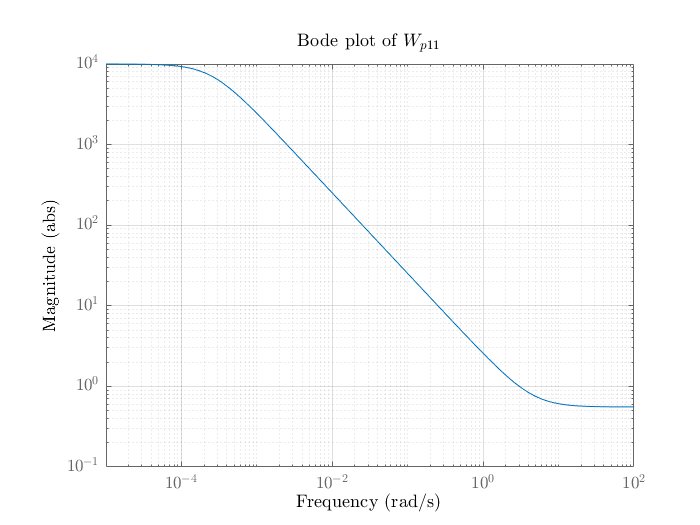

%Build blode plots
figure()
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
bodemag(Wp11)
grid on
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');
title('Bode plot of $W_{p11}$','interpreter', 'latex')
xlabel('Frequency','interpreter', 'latex')
ylabel('Magnitude','interpreter', 'latex')
saveas(gcf, 'Figures/ch2_mimo_weights_p_filter.eps',  'epsc')

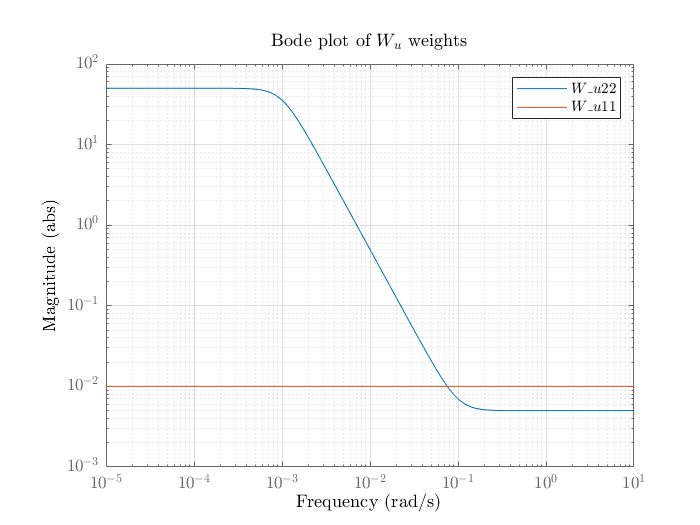


figure()

bodemag(Wu22)
title('Wu22'); grid on
hold on
bodemag(tf([0.01]))
setoptions(gcr,'MagUnits','abs', 'MagScale', 'log');
xlabel('Frequency','interpreter', 'latex')
ylabel('Magnitude','interpreter', 'latex')
title('Bode plot of $W_u$ weights','interpreter', 'latex')
legend("$W_{u22}$", "$W_{u11}$", 'Interpreter','latex')
saveas(gcf, 'Figures/ch2_mimo_weights_u_filter.eps',  'epsc')

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];
P11=[Wp; zeros(2,2)]; P12=[Wp*MIMO_ss; Wu]; P21=eye(2); P22=MIMO_ss;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 2, 2); %2 inputs, 2 outputs

H_inf_norm_CL = gamma

H_inf_norm_CL = 0.7993



%define inputnames of K
K.InputName = {'dOmega'; 'z (m)'}

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1   -0.0002513  -2.932e-16  -2.452e-16  -8.579e-16   -5.42e-15  -1.142e-16  -1.112e-13  -7.612e-17    -6.3e-17
   x2         2819      -36.09      -30.54      -104.9      -608.5      -15.67  -1.248e+04      -9.178      -7.098
   x3    7.459e-14           4  -7.281e-16  -2.548e-15  -1.609e-14   -3.39e-16  -3.302e-13   -2.26e-16  -1.871e-16
   x4    5.367e-15  -6.264e-17           1  -1.833e-16  -1.158e-15  -2.439e-17  -2.376e-14  -1.626e-17  -1.346e-17
   x5    5.111e-15  -5.966e-17   -4.99e-17         0.5  -1.103e-15  -2.323e-17  -2.263e-14  -1.549e-17  -1.282e-17
   x6     7.17e-15  -8.369e-17      -7e-17  -2.449e-16        0.25  -3.258e-17  -3.174e-14  -2.173e-17  -1.798e-17
   x7    1.584e-14  -1.849e-16  -1.546e-16  -5.409e-16  -3.417e-15    0.007812  -7.011e-14    -4.8e-17  -3.973e-17
   x8        808.4      -10.28      -7.901      -30.57      -173.9 

K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'}

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1   -0.0002513  -2.932e-16  -2.452e-16  -8.579e-16   -5.42e-15  -1.142e-16  -1.112e-13  -7.612e-17    -6.3e-17
   x2         2819      -36.09      -30.54      -104.9      -608.5      -15.67  -1.248e+04      -9.178      -7.098
   x3    7.459e-14           4  -7.281e-16  -2.548e-15  -1.609e-14   -3.39e-16  -3.302e-13   -2.26e-16  -1.871e-16
   x4    5.367e-15  -6.264e-17           1  -1.833e-16  -1.158e-15  -2.439e-17  -2.376e-14  -1.626e-17  -1.346e-17
   x5    5.111e-15  -5.966e-17   -4.99e-17         0.5  -1.103e-15  -2.323e-17  -2.263e-14  -1.549e-17  -1.282e-17
   x6     7.17e-15  -8.369e-17      -7e-17  -2.449e-16        0.25  -3.258e-17  -3.174e-14  -2.173e-17  -1.798e-17
   x7    1.584e-14  -1.849e-16  -1.546e-16  -5.409e-16  -3.417e-15    0.007812  -7.011e-14    -4.8e-17  -3.973e-17
   x8        808.4      -10.28      -7.901      -30.57      -173.9 

dOmega_sum = sumblk('dOmega = r - Omega (rad/s)')

dOmega_sum =
 
  From input "r" to output "dOmega":
  1
 
  From input "Omega (rad/s)" to output "dOmega":
  -1
 
Static gain.



reference tracking of $\omega_r$ and disturbance rejection of V

%build closed loop transfer function

%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'; 'z (m)'},{'Beta (deg)';'tau_e (Nm)'});
%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'z (m)';'Beta (deg)';'tau_e (Nm)'}

outputs_ = 6×1 cell array
    {'r'            }
    {'V (m/s)'      }
    {'Omega (rad/s)'}
    {'z (m)'        }
    {'Beta (deg)'   }
    {'tau_e (Nm)'   }


closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);
closed_loop = minreal(closed_loop);

22 states removed.



clf

figsize = [0,0,6,4 *6]

figsize =      0     0     6    24


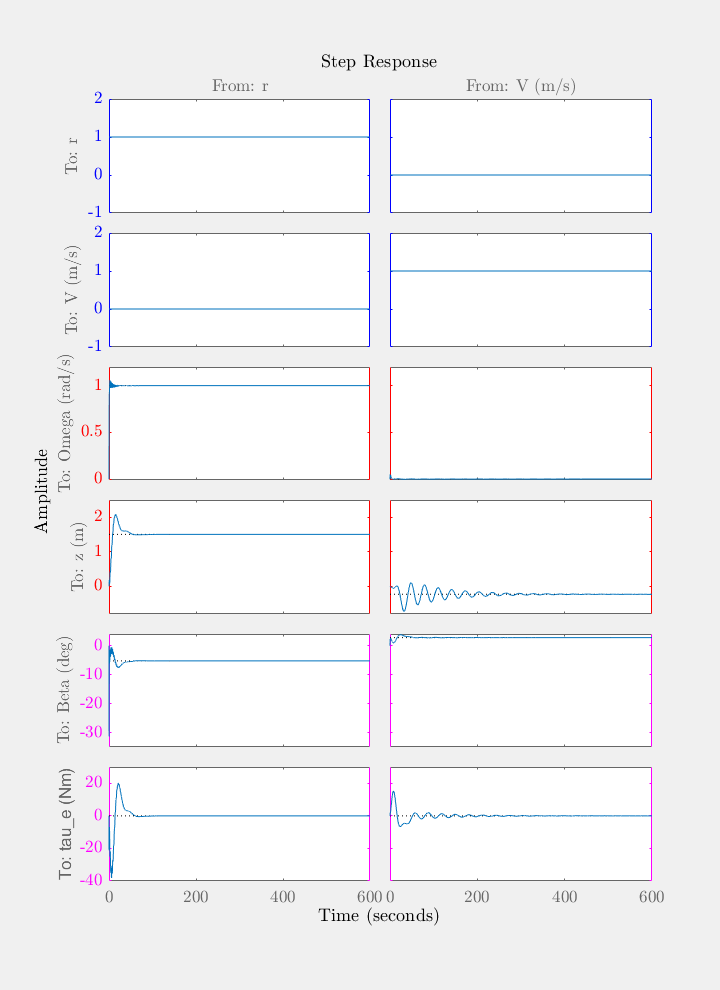


figure('units','inch','position',figsize);

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
step(closed_loop)
%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(12).YColor='Blue';
axs(13).YColor='Blue';
axs(7).YColor='Blue';
axs(6).YColor='Blue';

%outputs
axs(11).YColor='Red';
axs(10).YColor='Red';
axs(5).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(9).YColor='Magenta';
axs(8).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on')
xlabel('Time',"interpreter",'latex')
ylabel('Amplitude',"interpreter",'latex')
for i_ax = 7:13
    axs(i_ax).YLabel.Interpreter = 'latex';
end
hs = findall(gcf, 'type', 'axes');
for i= 1:length(hs)
    ha = get(hs(i), 'title');
    ha.Interpreter = 'latex';
end

saveas(gcf, 'Figures/ch2_mimo_simulation.eps',  'epsc')

%%%%%%%%%%%%%%

%L_ref = feedback(MIMO_ss, K, [1,2], [1,2], -1);
%L_dist = feedback(FWT, K, [1,2], [1,2], -1);